% Loading training data
load ActivityLogs

% Labeling the sitting data
sitLabel = 'sitting';
sitLabel = repmat(sitLabel, size(sitAcceleration, 1), 1);
sitAcceleration.Activity = sitLabel

sitAcceleration = 390×4 timetable
           Timestamp                X          Y         Z       Activity
    ________________________    _________    ______    ______    ________

    20-Jul-2023 13:34:44.644        2.138    3.1268    10.077    sitting 
    20-Jul-2023 13:34:44.724       1.1684    2.8754    8.8657    sitting 
    20-Jul-2023 13:34:44.804      0.93134     3.146     9.335    sitting 
    20-Jul-2023 13:34:44.884      0.69192    3.2729     8.746    sitting 
    20-Jul-2023 13:34:44.964       1.1851    3.3974    9.1722    sitting 
    20-Jul-2023 13:34:45.044       1.1803    3.4093    9.1626    sitting 
    20-Jul-2023 13:34:45.124       1.0654    3.3423    8.6335    sitting 
    


% Repeat for walking data
walkLabel = 'walking';
walkLabel = repmat(walkLabel, size(walkAcceleration, 1), 1);
walkAcceleration.Activity = walkLabel;

% Repeat for running data
runLabel = 'running';
runLabel = repmat(runLabel, size(runAcceleration, 1), 1);
runAcceleration.Activity = runLabel;

allAcceleration = [sitAcceleration; walkAcceleration; runAcceleration];
allAcceleration = timetable2table(allAcceleration, "ConvertRowTimes", false)

allAcceleration = 1121×4 table
        X          Y         Z       Activity
    _________    ______    ______    ________

        2.138    3.1268    10.077    sitting 
       1.1684    2.8754    8.8657    sitting 
      0.93134     3.146     9.335    sitting 
      0.69192    3.2729     8.746    sitting 
       1.1851    3.3974    9.1722    sitting 
       1.1803    3.4093    9.1626    sitting 
       1.0654    3.3423    8.6335    sitting 
       1.5778    3.5147    9.7779    sitting 
      0.76375    3.2801       8.6    sitting 
      0.98881    3.2537    9.2344    sitting 
       1.7238    4.1276    8.8992    sitting 
    -0.019154    2.9592     9.007    sitting 
      0.87149    2.6456     9.098    sitting 
       1.0343    3.0311    9.3781    sitting 
       1.1971    3.3686    9.2129    sitting 
      0.93134    3.4476     8.928    sitting 


% Feature extraction
allAcceleration.cumsumX = cumsum(table2array(allAcceleration(:, 1)))

allAcceleration = 1121×5 table
        X          Y         Z       Activity    cumsumX
    _________    ______    ______    ________    _______

        2.138    3.1268    10.077    sitting      2.138 
       1.1684    2.8754    8.8657    sitting     3.3064 
      0.93134     3.146     9.335    sitting     4.2377 
      0.69192    3.2729     8.746    sitting     4.9297 
       1.1851    3.3974    9.1722    sitting     6.1148 
       1.1803    3.4093    9.1626    sitting     7.2951 
       1.0654    3.3423    8.6335    sitting     8.3606 
       1.5778    3.5147    9.7779    sitting     9.9383 
      0.76375    3.2801       8.6    sitting     10.702 
      0.98881    3.2537    9.2344    sitting     11.691 
       1.7238    4.1276    8.8992    sitting     13.415 
    -0.019154    2.9592     9.007    sitting     13.396 


allAcceleration.cumsumY = cumsum(table2array(allAcceleration(:, 2)))

allAcceleration = 1121×6 table
        X          Y         Z       Activity    cumsumX    cumsumY
    _________    ______    ______    ________    _______    _______

        2.138    3.1268    10.077    sitting      2.138     3.1268 
       1.1684    2.8754    8.8657    sitting     3.3064     6.0023 
      0.93134     3.146     9.335    sitting     4.2377     9.1482 
      0.69192    3.2729     8.746    sitting     4.9297     12.421 
       1.1851    3.3974    9.1722    sitting     6.1148     15.818 
       1.1803    3.4093    9.1626    sitting     7.2951     19.228 
       1.0654    3.3423    8.6335    sitting     8.3606      22.57 
       1.5778    3.5147    9.7779    sitting     9.9383     26.085 
      0.76375    3.2801       8.6    sitting     10.702     29.365 
      0.98881   

allAcceleration.cumsumZ = cumsum(table2array(allAcceleration(:, 3)))

allAcceleration = 1121×7 table
        X          Y         Z       Activity    cumsumX    cumsumY    cumsumZ
    _________    ______    ______    ________    _______    _______    _______

        2.138    3.1268    10.077    sitting      2.138     3.1268     10.077 
       1.1684    2.8754    8.8657    sitting     3.3064     6.0023     18.943 
      0.93134     3.146     9.335    sitting     4.2377     9.1482     28.278 
      0.69192    3.2729     8.746    sitting     4.9297     12.421     37.024 
       1.1851    3.3974    9.1722    sitting     6.1148     15.818     46.196 
       1.1803    3.4093    9.1626    sitting     7.2951     19.228     55.359 
       1.0654    3.3423    8.6335    sitting     8.3606      22.57     63.992 
       1.5778    3.

classificationLearner % TrainClassifier2.m

% Loading testing data
load sittandeaxel.mat
testSitAcc = Acceleration

testSitAcc = 190×3 timetable
           Timestamp                X           Y         Z   
    ________________________    _________    _______    ______

    29-Sep-2023 14:32:31.263     -0.36135    0.03832    10.535
    29-Sep-2023 14:32:31.363     -0.17319     2.2733    10.977
    29-Sep-2023 14:32:31.463       1.8497     1.8448    8.9827
    29-Sep-2023 14:32:31.563       0.6272     1.1406    7.3065
    29-Sep-2023 14:32:31.663    -0.028441     2.9661    9.3338
    29-Sep-2023 14:32:31.763     -0.46733     3.8489    8.4037
    29-Sep-2023 14:32:31.863     -0.94978     2.7844    7.3409
    29-Sep-2023 14:32:31.962     -0.11317     3.0152    9.3696
    29-Sep-2023 14:32:32.062     -0.39383     2.471

sitLabel = 'sitting';
sitLabel = repmat(sitLabel, size(testSitAcc, 1), 1);
testSitAcc.Activity = sitLabel

testSitAcc = 190×4 timetable
           Timestamp                X           Y         Z       Activity
    ________________________    _________    _______    ______    ________

    29-Sep-2023 14:32:31.263     -0.36135    0.03832    10.535    sitting 
    29-Sep-2023 14:32:31.363     -0.17319     2.2733    10.977    sitting 
    29-Sep-2023 14:32:31.463       1.8497     1.8448    8.9827    sitting 
    29-Sep-2023 14:32:31.563       0.6272     1.1406    7.3065    sitting 
    29-Sep-2023 14:32:31.663    -0.028441     2.9661    9.3338    sitting 
    29-Sep-2023 14:32:31.763     -0.46733     3.8489    8.4037    sitting 
    29-Sep-2023 14:32:31.863     -0.94978     2.7844    7.3409    sitting 
    <s


load axel-walking.mat
testWalkAcc = Acceleration

testWalkAcc = 258×3 timetable
           Timestamp                X           Y          Z   
    ________________________    _________    ________    ______

    29-Sep-2023 14:33:27.279      -1.0312      1.5526    9.6753
    29-Sep-2023 14:33:27.378     -0.94738      1.6362    9.7034
    29-Sep-2023 14:33:27.478      -1.0062      1.5707    9.4102
    29-Sep-2023 14:33:27.578     -0.66791      1.1947     9.766
    29-Sep-2023 14:33:27.678     -0.36404      1.3171     9.745
    29-Sep-2023 14:33:27.778     -0.35312      1.5238    9.4521
    29-Sep-2023 14:33:27.878     -0.72255      1.6654    9.6159
    29-Sep-2023 14:33:27.978       -0.482      1.5717    9.4793
    29-Sep-2023 14:33:28.077      0.1576

walkLabel = 'walking';
walkLabel = repmat(walkLabel, size(testWalkAcc, 1), 1);
testWalkAcc.Activity = walkLabel;

load running
testRunAcc = Acceleration

testRunAcc = 551×3 timetable
           Timestamp                X          Y         Z   
    ________________________    _________    ______    ______

    29-Sep-2023 11:36:09.823     -0.13547    3.1271     7.997
    29-Sep-2023 11:36:09.922     0.073048    4.0642    8.3956
    29-Sep-2023 11:36:10.022      0.14205    3.5768    8.2065
    29-Sep-2023 11:36:10.122      0.35476     3.722     8.881
    29-Sep-2023 11:36:10.222      0.39623    3.4358    7.9455
    29-Sep-2023 11:36:10.322      0.37632    4.1349    8.2255
    29-Sep-2023 11:36:10.422     0.099693    4.6694    9.2069
    29-Sep-2023 11:36:10.522    -0.034877    4.3979    10.443
    29-Sep-2023 11:36:10.621      -1.6871    3.0789    9.7003

runLabel = 'running';
runLabel = repmat(runLabel, size(testRunAcc, 1), 1);
testRunAcc.Activity = runLabel;

allTestAcceleration = [testSitAcc; testWalkAcc; testRunAcc];
allTestAcceleration = timetable2table(allTestAcceleration, "ConvertRowTimes", false)

allTestAcceleration = 999×4 table
        X           Y         Z       Activity
    _________    _______    ______    ________

     -0.36135    0.03832    10.535    sitting 
     -0.17319     2.2733    10.977    sitting 
       1.8497     1.8448    8.9827    sitting 
       0.6272     1.1406    7.3065    sitting 
    -0.028441     2.9661    9.3338    sitting 
     -0.46733     3.8489    8.4037    sitting 
     -0.94978     2.7844    7.3409    sitting 
     -0.11317     3.0152    9.3696    sitting 
     -0.39383     2.4712    9.2996    sitting 
     -0.52705     2.6269    9.5825    sitting 
      -0.5028       2.97     9.429    sitting 
     -0.43125     2.6761     9.647    sitting 
      -0.3582     2.0717     9.795    sitting 
     -0.34653     1.4815    9.8215    sitting 
     -0.50804     1.4916     9.622    sitting 
     -0.51194     1.0704    9.

% Feature extraction
allTestAcceleration.cumsumX = cumsum(table2array(allTestAcceleration(:, 1)))

allTestAcceleration = 999×7 table
        X           Y         Z       Activity     cumsumX     cumsumY    cumsumZ
    _________    _______    ______    ________    _________    _______    _______

     -0.36135    0.03832    10.535    sitting      -0.36135    0.03832    10.535 
     -0.17319     2.2733    10.977    sitting      -0.53454     2.3116    21.512 
       1.8497     1.8448    8.9827    sitting        1.3152     4.1564    30.495 
       0.6272     1.1406    7.3065    sitting        1.9424      5.297    37.801 
    -0.028441     2.9661    9.3338    sitting        1.9139     8.2631    47.135 
     -0.46733     3.8489    8.4037    sitting        1.4466     12.112    55.539 
     -0.94978     2.7844    7.3409    sitting       0.49682     14.896 

allTestAcceleration.cumsumY = cumsum(table2array(allTestAcceleration(:, 2)))

allTestAcceleration = 999×7 table
        X           Y         Z       Activity     cumsumX     cumsumY    cumsumZ
    _________    _______    ______    ________    _________    _______    _______

     -0.36135    0.03832    10.535    sitting      -0.36135    0.03832    10.535 
     -0.17319     2.2733    10.977    sitting      -0.53454     2.3116    21.512 
       1.8497     1.8448    8.9827    sitting        1.3152     4.1564    30.495 
       0.6272     1.1406    7.3065    sitting        1.9424      5.297    37.801 
    -0.028441     2.9661    9.3338    sitting        1.9139     8.2631    47.135 
     -0.46733     3.8489    8.4037    sitting        1.4466     12.112    55.539 
     -0.94978     2.7844    7.3409    sitting       0.49682     14.896 

allTestAcceleration.cumsumZ = cumsum(table2array(allTestAcceleration(:, 3)))

allTestAcceleration = 999×7 table
        X           Y         Z       Activity     cumsumX     cumsumY    cumsumZ
    _________    _______    ______    ________    _________    _______    _______

     -0.36135    0.03832    10.535    sitting      -0.36135    0.03832    10.535 
     -0.17319     2.2733    10.977    sitting      -0.53454     2.3116    21.512 
       1.8497     1.8448    8.9827    sitting        1.3152     4.1564    30.495 
       0.6272     1.1406    7.3065    sitting        1.9424      5.297    37.801 
    -0.028441     2.9661    9.3338    sitting        1.9139     8.2631    47.135 
     -0.46733     3.8489    8.4037    sitting        1.4466     12.112    55.539 
     -0.94978     2.7844    7.3409    sitting       0.49682     14.896 

% Inference on activity data to predict sitting, walking, or running
yfit = trainedModel.predictFcn(allTestAcceleration)

yfit = 999×7 char array
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitti

% Visualization of results
% Test set accuracy
testAccuracy = sum(yfit == table2array(allTestAcceleration(:, 4))) / length(yfit)

testAccuracy =     0.4915    0.4915    0.4915    0.4915    1.0000    1.0000    1.0000


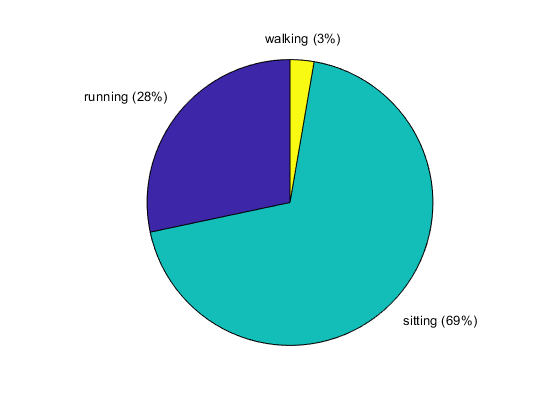


% Pie chart for the distribution
yfitcat = categorical(cellstr(yfit)); % convert to correct data type for histogram
pie(yfitcat)

% As a step function over time